# Pre-Process Data & Visualization

Sam Coleman and Rishita Sarin

%Load all JuniperSun Data
emgSets = [
load("JuniperSun/EMGdata-JuniperSun-03231513.mat");
load("JuniperSun/EMGdata-JuniperSun-03231520.mat");
load("JuniperSun/EMGdata-JuniperSun-03231522.mat");
load("JuniperSun/EMGdata-JuniperSun-03231525.mat");
load("JuniperSun/EMGdata-JuniperSun-03231527.mat");
load("JuniperSun/EMGdata-JuniperSun-03231528.mat");
load("JuniperSun/EMGdata-JuniperSun-03231531.mat");
load("JuniperSun/EMGdata-JuniperSun-03231534.mat");
load("JuniperSun/EMGdata-JuniperSun-03231535.mat");
load("JuniperSun/EMGdata-JuniperSun-03231539.mat");
];

%create fields,initialize with just values from first trial
emgAll = struct();
emgAll.setname = emgSets(1).EMG.setname;
emgAll.nbchan = emgSets(1).EMG.nbchan;
emgAll.srate = emgSets(1).EMG.srate;
emgAll.epochlabelscat = emgSets(1).EMG.epochlabelscat;
emgAll.data = emgSets(1).EMG.data;
emgAll.alltimes = emgSets(1).EMG.alltimes;
for i = 2:length(emgSets)
    emgAll.setname = [emgAll.setname emgSets(i).EMG.setname];
    emgAll.nbchan = [emgAll.nbchan emgSets(i).EMG.nbchan];
    emgAll.srate = [emgAll.srate emgSets(i).EMG.srate];
    emgAll.epochlabelscat = [emgAll.epochlabelscat emgSets(i).EMG.epochlabelscat];
    emgAll.data = cat(3, emgAll.data, emgSets(i).EMG.data);
    emgAll.alltimes = cat(3, emgAll.alltimes, emgSets(i).EMG.alltimes);
end

%mean center data
for channel =1:size(emgAll.data,1) 
    emgAll.data(channel,:, :) = emgAll.data(channel,:, :) - mean(emgAll.data(channel,:, :),2); 
end

%Visualizing Data
rock = emgAll.data(:, :, emgAll.epochlabelscat == 'rock');
paper = emgAll.data(:, :, emgAll.epochlabelscat == 'paper');
scissors = emgAll.data(:, :, emgAll.epochlabelscat == 'scissors');

rock_avg = mean(rock, 3);
paper_avg = mean(paper, 3);
scissors_avg = mean(scissors, 3);

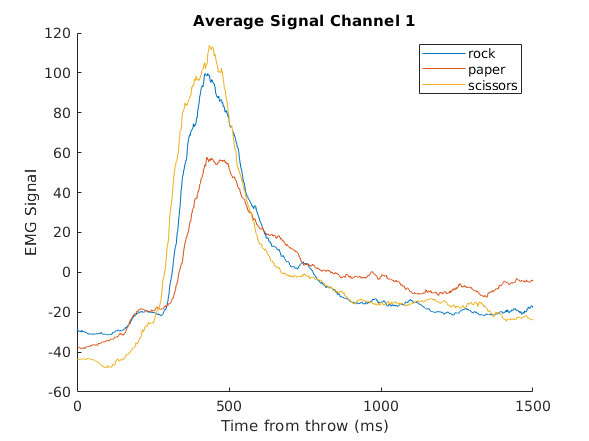

%channel 1
figure()
hold on
plot(rock_avg(1, :))
plot(paper_avg(1, :))
plot(scissors_avg(1,:))
title('Average Signal Channel 1')
xlabel('Time from throw (ms)')
ylabel('EMG Signal')
legend('rock', 'paper', 'scissors')
hold off

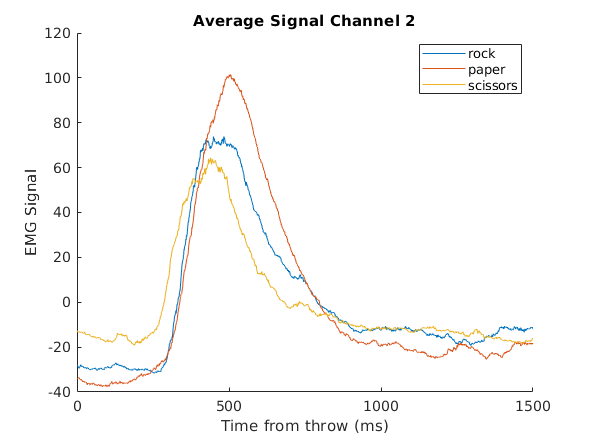


%channel 2
figure()
hold on
plot(rock_avg(2, :))
plot(paper_avg(2, :))
plot(scissors_avg(2,:))
title('Average Signal Channel 2')
xlabel('Time from throw (ms)')
ylabel('EMG Signal')
legend('rock', 'paper', 'scissors')
hold off

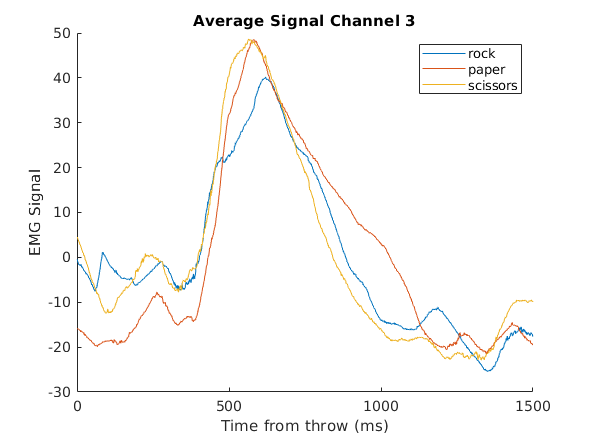


%channel 3
figure()
hold on
plot(rock_avg(3, :))
plot(paper_avg(3, :))
plot(scissors_avg(3,:))
title('Average Signal Channel 3')
xlabel('Time from throw (ms)')
ylabel('EMG Signal')
legend('rock', 'paper', 'scissors')
hold off

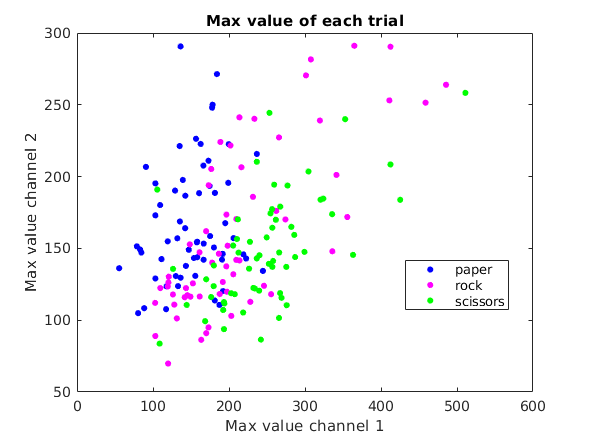

%Visualize max value with scatter plot
max_val_per_chan_trial = max(emgAll.data,[],2);
features= array2table(squeeze(max_val_per_chan_trial)','VariableNames',{'Ch1_max','Ch2_max', 'Ch3_max'});
gscatter(table2array(features(:,1)), table2array(features(:,2)), emgAll.epochlabelscat, "bmg")
title("Max value of each trial")
xlabel("Max value channel 1")
ylabel("Max value channel 2")

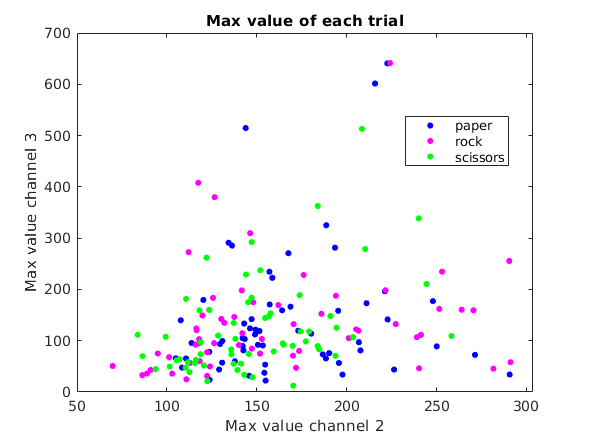


gscatter(table2array(features(:,2)), table2array(features(:,3)), emgAll.epochlabelscat, "bmg")
title("Max value of each trial")
xlabel("Max value channel 2")
ylabel("Max value channel 3")

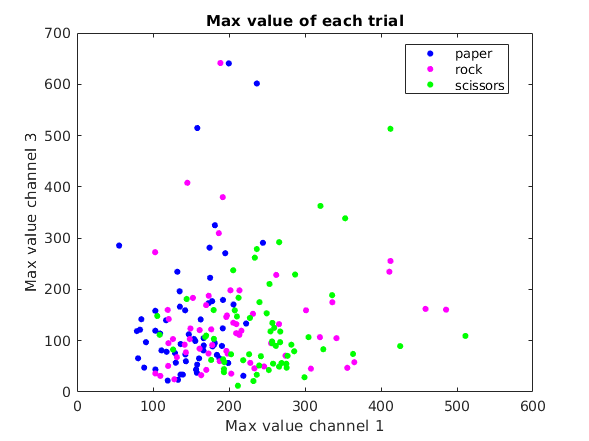



gscatter(table2array(features(:,1)), table2array(features(:,3)), emgAll.epochlabelscat, "bmg")
title("Max value of each trial")
xlabel("Max value channel 1")
ylabel("Max value channel 3")